SWDataPath_all = {...
    '/Volumes/PcSSDA/1610/20220219_1610_SW_002/',...
    '/Volumes/PcSSDA/1610/20220314_1610_SW_003/',...
    '/Volumes/PcSSDA/1610/20220328_1610_SW_005/',...
    '/Volumes/PcSSDA/1611/20220302_1611_SW_003/',...
    '/Volumes/PcSSDA/1611/20220316_1611_SW_004/',...
    '/Volumes/PcSSDA/1611/20220325_1611_SW_005/',...
    '/Volumes/PcSSDA/1612/20220301_1612_SW_003/',...
    '/Volumes/PcSSDA/1612/20220315_1612_SW_004/',...
    '/Volumes/PcSSDA/1612/20220324_1612_SW_005/',...
    '/Volumes/PcSSDA/1626/20220313_1626_SW_002/',...
    '/Volumes/PcSSDA/1626/20220318_1626_SW_003/',...
    '/Volumes/PcSSDA/1626/20220329_1626_SW_004/',...
    '/Volumes/PcSSDA/1629/20220312_1629_SW_002/',...
    '/Volumes/PcSSDA/1629/20220323_1629_SW_003/',...
    '/Volumes/PcSSDA/1629/20220331_1629_SW_004/',...
    '/Volumes/PcSSDA/1630/20220304_1630_SW_002/',...
    '/Volumes/PcSSDA/1630/20220319_1630_SW_003/',...
    '/Volumes/PcSSDA/1630/20220330_1630_SW_004/',...
    }

SWDataPath_all = 1×18 cell array
    {'/Volumes/PcSSDA/1610/20220219_1610_SW_002/'}    {'/Volumes/PcSSDA/1610/20220314_1610_SW_003/'}    {'/Volumes/PcSSDA/1610/20220328_1610_SW_005/'}    {'/Volumes/PcSSDA/1611/20220302_1611_SW_003/'}    {'/Volumes/PcSSDA/1611/20220316_1611_SW_004/'}    {'/Volumes/PcSSDA/1611/20220325_1611_SW_005/'}    {'/Volumes/PcSSDA/1612/20220301_1612_SW_003/'}    {'/Volumes/PcSSDA/1612/20220315_1612_SW_004/'}    {'/Volumes/PcSSDA/1612/20220324_1612_SW_005/'}    {'/Volumes/PcSSDA/1626/20220313_1626_SW_002/'}    {'/Volumes/PcSSDA/1626/20220318_1626_SW_003/'}    {'/Volumes/PcSSDA/1626/20220329_1626_SW_004/'}    {'/Volumes/PcSSDA/1629/20220312_1629_SW_002/'}    {'/Volumes/PcSSDA/1629/20220323_1629_SW_003/'}    {'/Volumes/PcSSDA/1629/20220331_1629_SW_004/'}    {'/Volumes/PcSSDA/1630/20220304_1630_SW_002/'}    {'/Volumes/PcSSDA/1630/20220319_1630_SW_003/'}    {'/Volumes/PcSSDA/1630/20220330_1630_SW_004/'}



Mouse_all = {'1610','1610','1610','1611','1611','1611','1612','1612','1612','1626','1626','1626','1629','1629','1629','1630','1630','1630'};
Time_all = {'1','2','3','1','2','3','1','2','3','1','2','3','1','2','3','1','2','3'};
Mouse_all_categorical = {'1610','1611','1612','1626','1629','1630',};

these_transitions = {'NREM-Active Wake','REM-Active Wake','NREM-REM','Active Wake-NREM',...
                    'NREM-Quiet Wake','REM-Quiet Wake','Active Wake-Quiet Wake','Quiet Wake-NREM',...
                     'Quiet Wake-Active Wake'}

these_transitions = 1×9 cell array
    {'NREM-Active Wake'}    {'REM-Active Wake'}    {'NREM-REM'}    {'Active Wake-NREM'}    {'NREM-Quiet Wake'}    {'REM-Quiet Wake'}    {'Active Wake-Quiet Wake'}    {'Quiet Wake-NREM'}    {'Quiet Wake-Active Wake'}



these_transitions_MATLAB = {'NREM_Active_Wake','REM_Active_Wake','NREM_REM','Active_Wake_NREM',...
                    'NREM_Quiet_Wake','REM_Quiet_Wake','Active_Wake_Quiet_Wake','Quiet_Wake_NREM',...
                     'Quiet_Wake_Active_Wake'}

these_transitions_MATLAB = 1×9 cell array
    {'NREM_Active_Wake'}    {'REM_Active_Wake'}    {'NREM_REM'}    {'Active_Wake_NREM'}    {'NREM_Quiet_Wake'}    {'REM_Quiet_Wake'}    {'Active_Wake_Quiet_Wake'}    {'Quiet_Wake_NREM'}    {'Quiet_Wake_Active_Wake'}


% Getting the F0 for each experiment
baseline_intensity_norm_all = zeros(length(SWDataPath_all), 1);

for i = 1:length(SWDataPath_all)
    concat_file = dir([SWDataPath_all{i}, 'concat_Acq*.mat']);
    load([SWDataPath_all{i}, concat_file.name])
    baseline_intensity_norm_all(i) = mean(photoncount_all, 'omitnan');
end


for i = 3%1:length(these_transitions_MATLAB)

    eval([these_transitions_MATLAB{i}, '_lifetime_MeanAndSEM = {};'])
    eval([these_transitions_MATLAB{i}, '_lifetime_MeanAndStd = {};'])

    eval([these_transitions_MATLAB{i}, '_intensity_MeanAndSEM = {};'])
    eval([these_transitions_MATLAB{i}, '_intensity_MeanAndStd = {};'])

end

% plot and save each individual transitions

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'


for i = 1:length(SWDataPath_all)

    PathToSave = [Summary_path, SWDataPath_all{i}(end-11:end-1), '_transitions_plot_1017/'];
    mkdir(PathToSave)

    for j = 2%1:length(these_transitions)

        intensity_csv = [SWDataPath_all{i}, these_transitions{j}, '_intensity.csv'];
        lifetime_csv = [SWDataPath_all{i}, these_transitions{j}, '_lifetime.csv'];
        time_csv = [SWDataPath_all{i}, these_transitions{j}, '_time.csv'];

        intensity_transitions = table2array(readtable(intensity_csv, 'NumHeaderLines', 1));
        lifetime_transitions = table2array(readtable(lifetime_csv, 'NumHeaderLines', 1));
        time_transitions = table2array(readtable(time_csv, 'NumHeaderLines', 1));

        num_of_transitions = min([size(time_transitions, 1), size(lifetime_transitions, 1), size(intensity_transitions, 1)]);

        for k = 1:num_of_transitions
            figure1 = figure('Visible', 'off');
%             subplot(2,1,1)
%             plot(time_transitons(k,:), lifetime_transitons(k,:), 'LineWidth', 3)
%             xlabel('Time (s)')
%             ylabel('Lifetime change (ns)')
%             xline([0])
% 
%             subplot(2,1,2)
%             plot(time_transitons(k,:), intensity_transitons(k,:), 'LineWidth', 3)
%             xlabel('Time (s)')
%             ylabel('Intensity change (ns)')
%             xline([0])
% 
%             sgtitle([these_transitions{j}, ' ', num2str(k)])

            plot_length = min([length(time_transitions(k,:)), length(lifetime_transitions(k,:)), length(intensity_transitions(k,:))]);
            baseline_index = find(time_transitions(k,:) <= -35);
            baseline_intensity = median(intensity_transitions(k, baseline_index));
            baseline_lifetime = median(lifetime_transitions(k, baseline_index));

            baseline_response_index = find(time_transitions(k,:) > -35 & time_transitions(k,:) <= -20);
            baseline_response_intensity = median(intensity_transitions(k, baseline_response_index));
            baseline_response_lifetime = median(lifetime_transitions(k, baseline_response_index));

            transition_response_index = find(time_transitions(k,:) > 20 & time_transitions(k,:) < 35);
            transition_response_intensity = median(intensity_transitions(k, transition_response_index));
            transition_response_lifetime = median(lifetime_transitions(k, transition_response_index));

            subplot(1,2,1)%yyaxis left
            plot(time_transitions(k,1:plot_length), lifetime_transitions(k,1:plot_length), 'LineWidth', 3)
            hold on
            plot(time_transitions(k,baseline_index), zeros(1, length(baseline_index))+ baseline_lifetime, 'LineWidth', 3, 'Color', 'k')
            hold on
            plot(time_transitions(k,baseline_response_index), zeros(1, length(baseline_response_index))+ baseline_response_lifetime, 'LineWidth', 3, 'Color', 'k')
            hold on
            plot(time_transitions(k,transition_response_index), zeros(1, length(transition_response_index))+ transition_response_lifetime, 'LineWidth', 3, 'Color', 'k')
            xlabel('Time (s)')
            ylabel('Lifetime change (ns)')
            xline([0])
            hold off
            subplot(1,2,2)%yyaxis right
            plot(time_transitions(k,1:plot_length), intensity_transitions(k,1:plot_length), 'LineWidth', 3)
            hold on
            plot(time_transitions(k,baseline_index), zeros(1, length(baseline_index))+ baseline_intensity, 'LineWidth', 3, 'Color', 'k')
            hold on
            plot(time_transitions(k,baseline_response_index), zeros(1, length(baseline_response_index))+ baseline_response_intensity, 'LineWidth', 3, 'Color', 'k')
            hold on
            plot(time_transitions(k,transition_response_index), zeros(1, length(transition_response_index))+ transition_response_intensity, 'LineWidth', 3, 'Color', 'k')
            xlabel('Time (s)')
            ylabel('Intensity change')
            xline([0])
%             yline([baseline_intensity baseline_response_intensity transition_response_intensity])
            title([these_transitions{j}, ' ', num2str(k)])
            hold off

            SaveFigureName = [PathToSave, these_transitions{j}, '_', num2str(k), '.png'];
            saveas(figure1, SaveFigureName)
        end
    end
end

% calculate the transition related change

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/';
FigureVisible = 'off';
PlotFigure = 0;
NREM_REM_intensity_change = {};
NREM_REM_lifetime_change = {};

NREM_REM_intensity_change_nested = {};
NREM_REM_lifetime_change_nested = {};

NREM_REM_intensity_change_pooled = {};
NREM_REM_lifetime_change_pooled = {};

NREM_REM_intensity_baseline_pooled = {};
NREM_REM_lifetime_baseline_pooled = {};

NREM_REM_label_pooled = {};

NREM_REM_intensity_baseline_nested = {};
NREM_REM_lifetime_baseline_nested = {};

for i =1:6
    NREM_REM_intensity_change{i} = [];
    NREM_REM_lifetime_change{i} = [];
end

for i =1:3
    NREM_REM_intensity_change_nested{i} = [];
    NREM_REM_lifetime_change_nested{i} = [];
    NREM_REM_label_pooled{i} = [];
end

for i =1:3
    NREM_REM_intensity_change_pooled{i} = [];
    NREM_REM_lifetime_change_pooled{i} = [];
end

for i =1:3
    NREM_REM_intensity_baseline_nested{i} = [];
    NREM_REM_lifetime_baseline_nested{i} = [];
end

for i =1:3
    NREM_REM_intensity_baseline_pooled{i} = [];
    NREM_REM_lifetime_baseline_pooled{i} = [];
end

i_animal_time_label = 1;
animal_time_label_categorical = {};


for i = 1:length(SWDataPath_all)

    i_mouse = (((i-1) - rem(i-1, 3))/3)+1;

    if rem(i, 3)
        i_time =  rem(i,3);
    else
        i_time = 3;
    end

    animal_time_label_categorical{i_animal_time_label} = [Mouse_all_categorical{i_mouse}];

%     mkdir([SWDataPath_all{i}, 'transitions_plot'])

    for j = 6 % 1:length(these_transitions)

        intensity_csv = [SWDataPath_all{i}, these_transitions{j}, '_intensity.csv'];
        lifetime_csv = [SWDataPath_all{i}, these_transitions{j}, '_lifetime.csv'];
        time_csv = [SWDataPath_all{i}, these_transitions{j}, '_time.csv'];

        intensity_transitions = table2array(readtable(intensity_csv, 'NumHeaderLines', 1));
        lifetime_transitions = table2array(readtable(lifetime_csv, 'NumHeaderLines', 1));
        time_transitions = table2array(readtable(time_csv, 'NumHeaderLines', 1));

        num_of_transitions = min([size(time_transitions, 1), size(lifetime_transitions, 1), size(intensity_transitions, 1)]);
        changes_intensity = zeros(num_of_transitions, 2);
        changes_lifetime = zeros(num_of_transitions, 2);
        labels = zeros(num_of_transitions, 2);
        

        for k = 1:num_of_transitions

            baseline_index = find(time_transitions(k,:) <= -35);
            baseline_intensity = median(intensity_transitions(k, baseline_index));
            baseline_lifetime = median(lifetime_transitions(k, baseline_index));

            baseline_response_index = find(time_transitions(k,:) > -35 & time_transitions(k,:) <= -20);
            baseline_response_intensity = median(intensity_transitions(k, baseline_response_index));
            baseline_response_lifetime = median(lifetime_transitions(k, baseline_response_index));

            transition_response_index = find(time_transitions(k,:) > 80 & time_transitions(k,:) < 100);
            transition_response_intensity = median(intensity_transitions(k, transition_response_index));
            transition_response_lifetime = median(lifetime_transitions(k, transition_response_index));

            baseline_change_intensity = (baseline_response_intensity - baseline_intensity)/baseline_intensity_norm_all(i);
            baseline_change_lifetime = baseline_response_lifetime - baseline_lifetime;

            transition_change_intensity = (transition_response_intensity - baseline_response_intensity)/baseline_intensity_norm_all(i);
            transition_change_lifetime = transition_response_lifetime - baseline_response_lifetime; 

            changes_intensity(k, 1) = baseline_change_intensity;
            changes_intensity(k, 2) = transition_change_intensity;

            changes_lifetime(k, 1) = baseline_change_lifetime;
            changes_lifetime(k, 2) = transition_change_lifetime;

            labels(k, 1) = i_animal_time_label;
            labels(k, 2) = k;


        end

        changes_intensity = [changes_intensity; nan(30 - num_of_transitions, 2)];
        changes_lifetime = [changes_lifetime; nan(30 - num_of_transitions, 2)];
        labels = [labels; nan(30 - num_of_transitions, 2)];

        NREM_REM_label_pooled{i_time} = [NREM_REM_label_pooled{i_time}; labels];

        NREM_REM_intensity_change{i_mouse} = [NREM_REM_intensity_change{i_mouse}, transpose(changes_intensity)];
        NREM_REM_lifetime_change{i_mouse} = [NREM_REM_lifetime_change{i_mouse}, transpose(changes_lifetime)];

        NREM_REM_intensity_change_nested{i_time} = [NREM_REM_intensity_change_nested{i_time}, changes_intensity(:,2)];
        NREM_REM_lifetime_change_nested{i_time} = [NREM_REM_lifetime_change_nested{i_time}, changes_lifetime(:,2)];

        NREM_REM_intensity_change_pooled{i_time} = [NREM_REM_intensity_change_pooled{i_time}; changes_intensity(:,2)];
        NREM_REM_lifetime_change_pooled{i_time} = [NREM_REM_lifetime_change_pooled{i_time}; changes_lifetime(:,2)];

        NREM_REM_intensity_baseline_nested{i_time} = [NREM_REM_intensity_baseline_nested{i_time}, changes_intensity(:,1)];
        NREM_REM_lifetime_baseline_nested{i_time} = [NREM_REM_lifetime_baseline_nested{i_time}, changes_lifetime(:,1)];

        NREM_REM_intensity_baseline_pooled{i_time} = [NREM_REM_intensity_baseline_pooled{i_time}; changes_intensity(:,1)];
        NREM_REM_lifetime_baseline_pooled{i_time} = [NREM_REM_lifetime_baseline_pooled{i_time}; changes_lifetime(:,1)];


        if PlotFigure
            figure('Visible',FigureVisible)
            sgtitle(these_transitions(j))
            subplot(1,2,1)
            scatter(zeros(num_of_transitions, 1), changes_lifetime(:,1), 30, 'filled')
            hold on
            scatter(ones(num_of_transitions, 1), changes_lifetime(:,2), 30, 'filled')
            ylabel('Lifetime change (ns)')
            title('Lifetime change')
            hold off
    
            subplot(1,2,2)
            scatter(zeros(num_of_transitions, 1), changes_intensity(:,1), 30, 'filled')
            hold on
            scatter(ones(num_of_transitions, 1), changes_intensity(:,2), 30, 'filled')
            ylabel('Intensity change')
            title('intensity change')
            hold off
            SaveFigureName = [Summary_path,'b_', SWDataPath_all{i}(end-11:end-1), '_', these_transitions{j}, '.png'];
            saveas(gcf, SaveFigureName)
        end

        

        
    end
    i_animal_time_label = i_animal_time_label + 1;
    
end

% check the outliers for REM-QW transitions
check_indexes = {};
check_index{1} = [97,102,121,155];
check_index{2} = 124;
check_index{3} = [91,92,98,103];
Outlier_recording = {};
Outlier_index = {};

for i = 1:3
    Outlier_recording{i} = animal_time_label_categorical(NREM_REM_label_pooled{i}(check_index{i},1))
    Outlier_index{i} = NREM_REM_label_pooled{i}(check_index{i},2)
end

Outlier_recording = 1×1 cell array
    {1×4 cell}


Outlier_index = 1×1 cell array
    {4×1 double}


Outlier_recording = 1×2 cell array
    {1×4 cell}    {1×1 cell}


Outlier_index = 1×2 cell array
    {4×1 double}    {[4]}


Outlier_recording = 1×3 cell array
    {1×4 cell}    {1×1 cell}    {1×4 cell}


Outlier_index = 1×3 cell array
    {4×1 double}    {[4]}    {4×1 double}


% change the data structure to copy and paste in prism
NREM_REM_lifetime_baseline = [NREM_REM_lifetime_baseline_pooled{1}, NREM_REM_lifetime_baseline_pooled{2}, NREM_REM_lifetime_baseline_pooled{3}]

NREM_REM_lifetime_baseline =     0.0015    0.0181   -0.0214
    0.0540    0.0190       NaN
    0.0101   -0.0048       NaN
       NaN   -0.0040       NaN
       NaN   -0.0031       NaN
       NaN    0.0065       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN


NREM_REM_lifetime_change = [NREM_REM_lifetime_change_pooled{1}, NREM_REM_lifetime_change_pooled{2}, NREM_REM_lifetime_change_pooled{3}]

NREM_REM_lifetime_change =    -0.0547   -0.0505       NaN
   -0.0259   -0.0686       NaN
       NaN   -0.0484       NaN
       NaN   -0.0629       NaN
       NaN   -0.0648       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN




NREM_REM_intensity_baseline = [NREM_REM_intensity_baseline_pooled{1}, NREM_REM_intensity_baseline_pooled{2}, NREM_REM_intensity_baseline_pooled{3}]

NREM_REM_intensity_baseline =    -0.0027    0.0409   -0.0248
    0.0849    0.0402       NaN
   -0.0049   -0.0104       NaN
       NaN    0.0041       NaN
       NaN   -0.0197       NaN
       NaN    0.0154       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN


NREM_REM_intensity_change = [NREM_REM_intensity_change_pooled{1}, NREM_REM_intensity_change_pooled{2}, NREM_REM_intensity_change_pooled{3}]

NREM_REM_intensity_change =    -0.0755   -0.0611       NaN
   -0.0235   -0.0899       NaN
       NaN   -0.0641       NaN
       NaN   -0.0990       NaN
       NaN   -0.0711       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN


% plot and save the average of each type of transitions; lifetime only

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'

time_transitions_plot = -50:1:100;

NREM_REM_num_of_NoNaN_all = {};
NREM_REM_intensity_all = [];
NREM_REM_lifetime_all = [];

for i = 1:length(SWDataPath_all)

    figure2 = figure('Visible','off');
    sgtitle(figure2, [SWDataPath_all{i}(end-11:end-8),' ', SWDataPath_all{i}(end-1)])

    for j = 3%1:length(these_transitions)

        intensity_csv = [SWDataPath_all{i}, these_transitions{j}, '_intensity.csv'];
        lifetime_csv = [SWDataPath_all{i}, these_transitions{j}, '_lifetime.csv'];
        time_csv = [SWDataPath_all{i}, these_transitions{j}, '_time.csv'];

        intensity_transitions = table2array(readtable(intensity_csv, 'NumHeaderLines', 1));
        lifetime_transitions = table2array(readtable(lifetime_csv, 'NumHeaderLines', 1));
        time_transitions = table2array(readtable(time_csv, 'NumHeaderLines', 1));

        num_of_transitions = min([size(time_transitions, 1), size(lifetime_transitions, 1), size(intensity_transitions, 1)]);
        length_of_plot = min([size(time_transitions, 2), size(lifetime_transitions, 2), size(intensity_transitions, 2)]);
        x_axis_plot = -49:1:length_of_plot-50;

        if num_of_transitions == 1

            lifetime_transition_mean = lifetime_transitions;
            intensity_transition_mean = intensity_transitions;

            lifetime_transition_std = NaN(1, length_of_plot);
            intensity_transition_std = NaN(1, length_of_plot);
        else

            lifetime_transition_mean = mean(lifetime_transitions, 'omitnan');
            intensity_transition_mean = mean(intensity_transitions, 'omitnan');
    
            lifetime_transition_std = std(lifetime_transitions, 'omitnan');
            intensity_transition_std = std(intensity_transitions, 'omitnan');

        end

        lifetime_transition_sem = NaN(1, length_of_plot);
        intensity_transition_sem = NaN(1, length_of_plot);


        num_of_NoNaN = zeros(length_of_plot, 1);
        for i_plot = 1:length_of_plot
            num_of_NoNaN(i_plot) = num_of_transitions - sum(isnan(lifetime_transitions(:,i_plot)));
            if num_of_NoNaN(i_plot) > 0
                lifetime_transition_sem(i_plot) = lifetime_transition_std(i_plot)/sqrt(num_of_NoNaN(i_plot));
                intensity_transition_sem(i_plot) = intensity_transition_std(i_plot)/sqrt(num_of_NoNaN(i_plot));
            end
        end

        eval([these_transitions_MATLAB{j}, '_num_of_NoNaN_all{i} = num_of_NoNaN;'])

        eval([these_transitions_MATLAB{j}, '_lifetime_MeanAndSEM{i} = transpose([lifetime_transition_mean;lifetime_transition_sem]);'])
        eval([these_transitions_MATLAB{j}, '_lifetime_MeanAndStd{i} = transpose([lifetime_transition_mean;lifetime_transition_std]);'])

        eval([these_transitions_MATLAB{j}, '_intensity_MeanAndSEM{i} = transpose([intensity_transition_mean;intensity_transition_sem]);'])
        eval([these_transitions_MATLAB{j}, '_intensity_MeanAndStd{i} = transpose([intensity_transition_mean;intensity_transition_std]);'])

        subplot1 = subplot(3,3,j, 'Parent', figure2);
        hold(subplot1, "on")
        errorbar(x_axis_plot,lifetime_transition_mean,lifetime_transition_sem, 'CapSize',0,'LineWidth', 3, 'Color', 'cyan')
        plot(x_axis_plot,lifetime_transition_mean,'Color','r', 'LineWidth',2)
%         ylim([-0.1 0.1])
%         yticks([-0.05 0 0.05])
        xline([0])
        if sum(j == [7 8 9]) > 0
            xlabel('Time (s)')
        end

        if sum(j == [1 4 7]) > 0
            ylabel('Lifetime change (ns)')
        end
        title(these_transitions{j})
        box off
        hold(subplot1, "off")
    end
    SaveFigureName_mouse_lifetime = [Summary_path, 'a_',SWDataPath_all{i}(end-11:end-1),'_lifetime.png'];
    saveas(figure2, SaveFigureName_mouse_lifetime)

end


% pool all the transition traces together and plot an average trace;
% lifetime and intensity

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'

cd(Summary_path)
time_transitions_plot = -49:1:100;
num_of_transitions_individual = 0;
num_of_transitions_accum = [];


% for i_mouse_rmv = 1:5
intensity_transitions = [];
lifetime_transitions = [];

for i = 1:length(SWDataPath_all)
    
    mouse_ID = Mouse_all{i};
    
    if rem(i, 3)
        i_time =  rem(i,3);
    else
        i_time = 3;
    end



    j = 2;%1:length(these_transitions);

    intensity_csv = [SWDataPath_all{i}, these_transitions{j}, '_intensity.csv'];
    lifetime_csv = [SWDataPath_all{i}, these_transitions{j}, '_lifetime.csv'];
    time_csv = [SWDataPath_all{i}, these_transitions{j}, '_time.csv'];

    intensity_read = table2array(readtable(intensity_csv, 'NumHeaderLines', 1));
    lifetime_read = table2array(readtable(lifetime_csv, 'NumHeaderLines', 1));
    time_read = table2array(readtable(time_csv, 'NumHeaderLines', 1));

    length_of_plot = min([size(lifetime_read, 2), size(intensity_read, 2)]);
    num_of_transitions = min([size(lifetime_read, 1), size(intensity_read, 1)]);

    intensity_read = intensity_read/baseline_intensity_norm_all(i);

    intensity_read = [intensity_read nan(num_of_transitions, 150 - length_of_plot)];
    lifetime_read = [lifetime_read nan(num_of_transitions, 150 - length_of_plot)];

%     for i_rmv_index = 1:length(Outlier_recording{i_time})
%         if sum(mouse_ID == '1611') == 4 %& i_time == 3%Outlier_recording{i_time}{i_rmv_index}
% %             intensity_read(Outlier_index{i_time}(i_rmv_index), :) = NaN(1, 150);
% %             mouse_rmvd = Mouse_all_categorical{i_mouse_rmv};
%             intensity_read = NaN(1, 150);
%             lifetime_read = NaN(1, 150);
%         end
%     end


    intensity_transitions = [intensity_transitions; intensity_read];
    lifetime_transitions = [lifetime_transitions; lifetime_read];

    num_of_transitions_individual = size(intensity_read, 1) + num_of_transitions_individual;
    num_of_transitions_accum = [num_of_transitions_accum, num_of_transitions_individual];

end



num_of_transitions = min([size(lifetime_transitions, 1), size(intensity_transitions, 1)])

num_of_transitions = 67

length_of_plot = min([size(time_transitions_plot, 2), size(lifetime_transitions, 2), size(intensity_transitions, 2)]);
x_axis_plot = -49:1:length_of_plot-50;



lifetime_transition_mean = mean(lifetime_transitions, 'omitnan');
intensity_transition_mean = mean(intensity_transitions, 'omitnan');

lifetime_transition_std = std(lifetime_transitions, 'omitnan');
intensity_transition_std = std(intensity_transitions, 'omitnan');


lifetime_transition_sem = NaN(1, length_of_plot);
intensity_transition_sem = NaN(1, length_of_plot);


num_of_NoNaN = zeros(length_of_plot, 1);
for i_plot = 1:length_of_plot
    num_of_NoNaN(i_plot) = num_of_transitions - sum(isnan(lifetime_transitions(:,i_plot)));
    if num_of_NoNaN(i_plot) > 0
        lifetime_transition_sem(i_plot) = lifetime_transition_std(i_plot)/sqrt(num_of_NoNaN(i_plot));
        intensity_transition_sem(i_plot) = intensity_transition_std(i_plot)/sqrt(num_of_NoNaN(i_plot));
    end
end

figure('Visible', 'off')
sgtitle([these_transitions{j}, ' ', ', n = ', num2str(num_of_transitions)])
subplot(2,1,1)
errorbar(x_axis_plot,lifetime_transition_mean,lifetime_transition_sem, 'CapSize',0,'LineWidth', 3, 'Color', 'cyan')
hold on
scatter(x_axis_plot,lifetime_transition_mean,'Color','r', 'LineWidth',2)
%         ylim([-0.1 0.1])
%         yticks([-0.05 0 0.05])
xline([-40 -30 -20 -10 0 10 20 30 40 50])
xticks([-40 -30 -20 -10 0 10 20 30 40 50])
xlabel('Time (s)')
ylabel('Lifetime change (ns)')
box off
hold off
subplot(2,1,2)
errorbar(x_axis_plot,intensity_transition_mean,intensity_transition_sem, 'CapSize',0,'LineWidth', 2, 'Color', 'cyan')
hold on
scatter(x_axis_plot,intensity_transition_mean,'Color','r', 'LineWidth',2)
xline([-40 -30 -20 -10 0 10 20 30 40 50])
xticks([-40 -30 -20 -10 0 10 20 30 40 50])
% ylim([-0.05,0.05])
xlabel('Time (s)')
ylabel('Intensity change')
box off
hold off

savename = [these_transitions_MATLAB{j}, ' ', '.png'];
saveas(gcf, savename)

% end

%     SaveFigureName_mouse_lifetime = [Summary_path, 'a_',SWDataPath_all{i}(end-11:end-1),'_lifetime.png'];
%     saveas(figure2, SaveFigureName_mouse_lifetime)



% plot and save the average of each type of transitions; intensity only

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'


for i = 1:length(SWDataPath_all)
   
    figure3 = figure('Visible','off');
    sgtitle(figure3, [SWDataPath_all{i}(end-11:end-8),' ', SWDataPath_all{i}(end-1)])


    for j = 1:length(these_transitions)

        intensity_csv = [SWDataPath_all{i}, these_transitions{j}, '_intensity.csv'];
        lifetime_csv = [SWDataPath_all{i}, these_transitions{j}, '_lifetime.csv'];
        time_csv = [SWDataPath_all{i}, these_transitions{j}, '_time.csv'];

        intensity_transitions = table2array(readtable(intensity_csv, 'NumHeaderLines', 1));
        lifetime_transitions = table2array(readtable(lifetime_csv, 'NumHeaderLines', 1));
        time_transitions = table2array(readtable(time_csv, 'NumHeaderLines', 1));

        num_of_transitions = min([size(time_transitions, 1), size(lifetime_transitions, 1), size(intensity_transitions, 1)]);
        length_of_plot = min([size(time_transitions, 2), size(lifetime_transitions, 2), size(intensity_transitions, 2)]);
        x_axis_plot = -49:1:length_of_plot-50;

        if num_of_transitions == 1

            lifetime_transition_mean = lifetime_transitions;
            intensity_transition_mean = intensity_transitions;

            lifetime_transition_std = NaN(1, length_of_plot);
            intensity_transition_std = NaN(1, length_of_plot);
        else

            lifetime_transition_mean = mean(lifetime_transitions, 'omitnan');
            intensity_transition_mean = mean(intensity_transitions, 'omitnan');
    
            lifetime_transition_std = std(lifetime_transitions, 'omitnan');
            intensity_transition_std = std(intensity_transitions, 'omitnan');

        end

        lifetime_transition_sem = NaN(1, length_of_plot);
        intensity_transition_sem = NaN(1, length_of_plot);

        for i_plot = 1:length_of_plot
            num_of_NoNaN = num_of_transitions - sum(isnan(lifetime_transitions(:,i_plot)));
            if num_of_NoNaN > 0
                lifetime_transition_sem(i_plot) = lifetime_transition_std(i_plot)/sqrt(num_of_NoNaN);
                intensity_transition_sem(i_plot) = intensity_transition_std(i_plot)/sqrt(num_of_NoNaN);
            end
        end

        eval([these_transitions_MATLAB{j}, '_lifetime_MeanAndSEM{i} = transpose([lifetime_transition_mean;lifetime_transition_sem]);'])
        eval([these_transitions_MATLAB{j}, '_lifetime_MeanAndStd{i} = transpose([lifetime_transition_mean;lifetime_transition_std]);'])

        eval([these_transitions_MATLAB{j}, '_intensity_MeanAndSEM{i} = transpose([intensity_transition_mean;intensity_transition_sem]);'])
        eval([these_transitions_MATLAB{j}, '_intensity_MeanAndStd{i} = transpose([intensity_transition_mean;intensity_transition_std]);'])

        subplot2 = subplot(3,3,j, 'Parent', figure3);
        hold(subplot2, "on")
        errorbar(x_axis_plot,intensity_transition_mean,intensity_transition_sem, 'CapSize',0,'LineWidth', 2, 'Color', 'cyan')
        plot(x_axis_plot,intensity_transition_mean,'Color','r', 'LineWidth',2)
%         ylim([-0.1 0.1])
%         yticks([-0.05 0 0.05])
        xline([0])
        if sum(j == [7 8 9]) > 0
            xlabel('Time (s)')
        end
        if sum(j == [1 4 7]) > 0
            ylabel('Intensity change')
        end
        title(these_transitions{j})
        box off
        hold(subplot2, "off")

    end

    SaveFigureName_mouse_intensity = [Summary_path, 'a_',SWDataPath_all{i}(end-11:end-1),'_intensity.png'];
    saveas(figure3, SaveFigureName_mouse_intensity)
end



figure
h = errorbar(x,a,b1, 'CapSize',0,'LineWidth', 3, 'Color', 'cyan')

h =   ErrorBar with properties:

             Color: [0 1 1]
         LineStyle: '-'
         LineWidth: 3
            Marker: 'none'
             XData: [-49 -48 -47 -46 -45 -44 -43 -42 -41 -40 -39 -38 -37 -36 -35 -34 -33 -32 -31 -30 -29 -28 -27 -26 -25 -24 -23 -22 -21 -20 -19 -18 -17 -16 -15 -14 -13 -12 -11 -10 -9 -8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 … ]
             YData: [-0.0131 -0.0140 -0.0111 -0.0121 -0.0196 -0.0181 -0.0183 -0.0176 -0.0146 -0.0170 -0.0187 -0.0138 -0.0207 -0.0186 -0.0182 -0.0203 -0.0180 -0.0171 -0.0174 -0.0178 -0.0157 -0.0172 -0.0187 -0.0197 -0.0162 -0.0190 -0.0177 -0.0164 … ]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0046 0.0062 0.0060 0.0085 0.0066 0.0069 0.0070 0.0072 0.0057 0.0069 0.0063 0.0081 0.0081 0.0069 0.0078 0.0062 0.0090 0.0090 0.0076 0.0080 0.0065 0.0068 0.0051 0.0060 0.0077 0.006

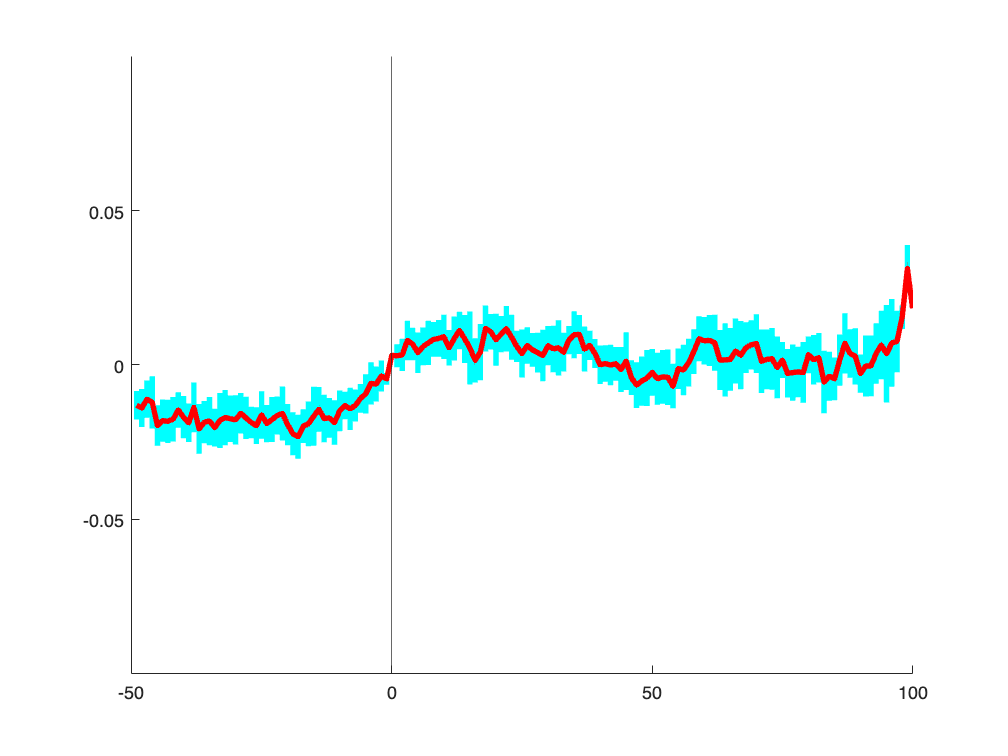

hold on
plot(x,a,'Color','r', 'LineWidth',3)
ylim([-0.1 0.1])
yticks([-0.05 0 0.05])
xline([0])
box off

% moving all 
Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'

Summary_path = '/Volumes/PcSSDA/Transition_plots_summary/'


for i = 1:length(SWDataPath_all)

    lifetime_transition_plot = [SWDataPath_all{i}, 'lifetime_Transitions.png'];
    intensity_transition_plot = [SWDataPath_all{i}, 'intensity_Transitions.png'];

    moved_file_name_lifetime = [Summary_path, SWDataPath_all{i}(end-11:end-1), '_lifetime_transitons.png'];
    moved_file_name_intensity = [Summary_path, SWDataPath_all{i}(end-11:end-1), '_intensity_transitons.png'];

    copyfile(lifetime_transition_plot, moved_file_name_lifetime)
    copyfile(intensity_transition_plot, moved_file_name_intensity)


end
